This script is designed to calculate the possible modes of a cylindrical resonator. 

Note this only finds the TM modes.

clear all
close all
fmin = 200e6;
fmax = 1e9;
a = log10(fmin); %start frequency
b = log10(fmax); %end frequency
omega = 2*pi*logspace(a,b, 20000);


Although we can guess approximately the maximum possible longitudinal modes, we don't bother and simply calculate the first 10 as if they exist

long_mode_num = 1:10;

The cavity dimsions need to be set in lines 7 and 8. This is then used to calculate the longitudinal wavevector of each longitudinal mode.

cavity_length = 41.4e-2;
cavity_width = 17.35e-2;
cavity_depth = 25.45e-2;
sub_length = cavity_length/3;

We choose to look for all the modes up to 10,10,10 (l,m,p)

There are two sets of TE modes (the TM modes are degenerate, so for each TE mode there is an identical TM mode). The modes are defined with respect to the length of the resonator (longitudinal mode *l*) and **one** transverse direction (*m* or *p*)

l = 1:1:11;
m = 0:1:10;
p = 0:1:10;
c = 300e6;
q = 1;
ld_TE_c1 = zeros(1,length(l)*length(m)*length(p));
TE_mode_size_c1 = zeros(1,length(l)*length(m)*length(p));
ld_TE_c2 = zeros(1,length(l)*length(m)*length(p));
TE_mode_size_c2 = zeros(1,length(l)*length(m)*length(p));
ld_TE_c3 = zeros(1,length(l)*length(m)*length(p));
TE_mode_size_c3 = zeros(1,length(l)*length(m)*length(p));
for j= l
    for k = m
        %disp(q)
        ld_TE_c1(q:(length(p)+q-1)) = 2./(sqrt((j./cavity_length).^2 + (k./cavity_width).^2 + (p./cavity_depth).^2));
        TE_mode_size_c1(q:(length(p)+q-1)) = 1./(j*(k+1).*(p+1));
        ld_TE_c2(q:(length(p)+q-1)) = 2./(sqrt((j./sub_length).^2 + (k./cavity_width).^2 + (p./cavity_depth).^2));
        TE_mode_size_c2(q:(length(p)+q-1)) = 3./(j*(k+1).*(p+1));
        ld_TE_c3(q:(length(p)+q-1)) = 2./(sqrt((j./(2.*sub_length)).^2 + (k./cavity_width).^2 + (p./cavity_depth).^2));
        TE_mode_size_c3(q:(length(p)+q-1)) = 2./(j*(k+1).*(p+1));
        q = q + length(p);
    end
end
TE_mode_freq_1 = c./ld_TE_c1;
TE_mode_freq_2 = c./ld_TE_c2;
TE_mode_freq_3 = c./ld_TE_c3;
TE_com_modes = zeros(1, length(TE_mode_freq_1));
q = 1;
for j = 1:length(TE_mode_freq_1)
    diff1 = abs(TE_mode_freq_1(j) - TE_mode_freq_2) < 25e6;
    diff2 = abs(TE_mode_freq_1(j) - TE_mode_freq_3) < 25e6;
    if (any(diff1) && any(diff2))
        TE_com_modes(q) = TE_mode_freq_1(j);
        q = q+ 1;
    end
end
TE_modes = TE_com_modes(TE_com_modes>0);
TE_mode_amp = TE_mode_size_c1(TE_com_modes>0).*TE_mode_size_c2(TE_com_modes>0).*TE_mode_size_c3(TE_com_modes>0);
disp('done, plotting')

done, plotting


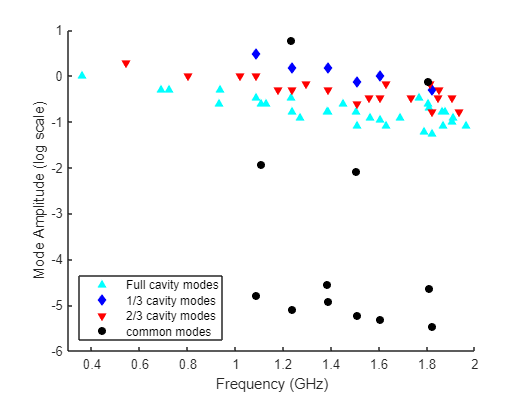


%TM_mode_num = [l; m; p]';
%TM_mode_labels = createModeLabels(TM_mode_num);
TE_mode_num = [l; m; p]';
%TE_mode_labels = createModeLabels(TE_mode_num);
figure()
scatter(TE_mode_freq_1/1e9, log10(TE_mode_size_c1),36,'cyan', 'filled','^');%, mode_omega, mode_num_n, mode_omega, mode_num_k);
%text(TE_mode_freq/1e9-0.015, TE_mode_size+0.025, TE_mode_labels)
xlabel("Frequency (GHz)")
ylabel("Mode Amplitude (log scale)")
%ylim([0,3.1]);
xlim([0.3,2]);
hold on
scatter(TE_mode_freq_2/1e9, log10(TE_mode_size_c2),36,'blue', 'filled','d');%, mode_omega, mode_num_n, mode_omega, mode_num_k);
scatter(TE_mode_freq_3/1e9, log10(TE_mode_size_c3),36,'red', 'filled','v');%, mode_omega, mode_num_n, mode_omega, mode_num_k);
scatter(TE_modes/1e9, log10(TE_mode_amp),36,'black', 'filled','o');%, mode_omega, mode_num_n, mode_omega, mode_num_k);
legend({'Full cavity modes', '1/3 cavity modes', '2/3 cavity modes', 'common modes'}, 'location', 'southwest')

%plot(TE_mode_omega/(2*pi*1e9), TE_mode_size, 'o');%, mode_omega, mode_num_n, mode_omega, mode_
% num_k);
%text(TE_mode_omega/(2*pi*1e9)-0.015, TE_mode_size-0.025, TE_mode_labels)
%disp(omega_r/(2*pi))


The function below searches for radial wavevectors that are real. Note in line 48, we have the equation 


$$k_r^2 = \frac{\omega^2}{c^2} - k_l^2$$


where $k_r$ is the radial wavevector, $k_l$ is the longitudinal wavevector, $\omega$ is the angular frequency and $c$ is the speed of light. When $k_l>\omega^2/c^2$ then $k_r$ is imaginary and the mode can no longer resonate. We use this condition to find modes. However, a second selection is made against high frequency modes for which the radial wavevector is real for only a few frequencies (these are very close to the cutoff of the resonator).

function [k_spatial, omega_selected, useful] = findRealWavevectors(omega, k_long)
    c=300e6;
    k_spatial_squared = omega.^2./c^2 - k_long.^2;
    idxes = find(k_spatial_squared > 0);
    k_spatial = sqrt(k_spatial_squared(idxes));
    omega_selected = omega(idxes);
    if length(k_spatial)>100
        useful = true;
    else
        useful = false;
    end
end


This function searches for the spatial modes of TM modes. Each mode is a bessel function and must be zero at the boundary of the resonator. Thus, we search for frequencies for which this is true. However, this also picks up many potential modes that have nearly zero amplitude. So, we also insist that the maximum value is greater than 0.1 (the max value of the bessel's function is 1).

function [om_sel, mode_amp, use_val] = findTMSpatialMode(n, k, cw, omega)
    


    boundary_value = cos(n*k.*cw);
    %boundary_value = besselj(n, k.*cw);
    %find for which spatial modes the amplitude is zero at the 
    %cavity bounday
    potential_zeros = boundary_value.^2 < 1e-8; %this will be logical true for small amplitudes of boundary_value
    diff_zeros = zeros(size(potential_zeros));
    diff_zeros(2:end) = diff(potential_zeros) ~= 0; %this will be logically true when two adjacent values are different
    diff_zeros(1) = potential_zeros(1);
    adj_vals = potential_zeros.*diff_zeros; %this is true when adjacent values are different and one 
    % of them has a small amplitude
    jdxes = find(adj_vals);
    use_val = false;
    om_sel(1) = 0;
    mode_amp(1) = 0;
    if ~isempty(jdxes)
        l = 1;
        r = linspace(0, cw, 100);
        for j = jdxes
            mode_amp_func = besselj(n, (k(j).*r));
            if max(abs(mode_amp_func) > 0.1)
                %mode has amplitude
                om_sel(l) = omega(j);
                mode_amp(l) = max(abs(mode_amp_func));
                use_val = true;
                l = l + 1;
            end
        end
    end
end

For TE modes, we require that the **derivative** of the Bessel's function is 0 at the boundary. To calculate the derivative, we make use of the following identity


$$\frac{\partial J_m(z)}{\partial z} = \frac{1}{2}\left[J_{m-1}(z) - J_{m+1}(z)\right]$$


where $m$ is the order of the Bessel's function ($n$ in the code below) and $z$ is the argument of the Bessel's function. For the 0th order Bessel's function, the derivative is given by $\partial J_0(z)/\partial z = -J_1(z)$. As with the code for the TM mode finder, we also check that the amplitude of the mode is sufficiently large.

One of the issues with using a threshold is that adjacent values can fall under the threshold. To prevent this, we use diff

function [om_sel, mode_amp, use_val] = findTESpatialMode(n, k, cw, omega)
    if n == 0
        boundary_value = -1*besselj(1, k.*cw);
    else
        boundary_value = 0.5.*(besselj(n-1, k.*cw) - besselj(n+1, k.*cw));
    end
    %find for which spatial modes the amplitude is zero at the 
    %cavity bounday
    
    potential_zeros = boundary_value.^2 < 1e-8; %this will be logical true for small amplitudes of boundary_value
    diff_zeros = zeros(size(potential_zeros));
    diff_zeros(2:end) = diff(potential_zeros) ~= 0; %this will be logically true when two adjacent values are different
    diff_zeros(1) = potential_zeros(1);
    adj_vals = potential_zeros.*diff_zeros; %this is true when adjacent values are different and one 
    % of them has a small amplitude
    
    jdxes = find(adj_vals);
    use_val = false;
    om_sel(1) = 0;
    mode_amp(1) = 0;
    if ~isempty(jdxes)
        l = 1;
        r = linspace(0, cw, 100);
        for j = jdxes
            mode_amp_func = besselj(n, (k(j).*r));
            if max(abs(mode_amp_func) > 0.1)
                %mode has amplitude
                om_sel(l) = omega(j);
                mode_amp(l) = max(abs(mode_amp_func));
                use_val = true;
                l = l + 1;
            end
        end
    end
end

This is an auxilary function that takes the mode labels and turns them into lines of text to display on the graph.

function mode_labels = createModeLabels(mode_num)
    %len = length(mode_num);
    len = size(mode_num);
    string_mode_num = string(mode_num);
    for j = 1:len
        mode_labels(j) = strcat(string_mode_num(j,1), ",", string_mode_num(j,2), ",", string_mode_num(j,3));
    end
end
